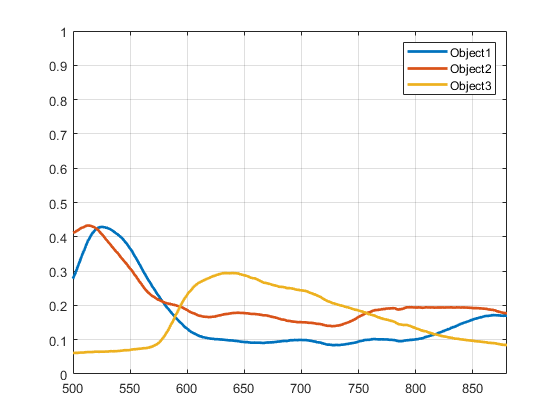

close all;
clear;
clc;
%% Моделирование регистрации сигнала многоканальным ПИ (Этап 1)
load('ChannelMatrixDZ.mat');
load('ObjectDifSpectrMatrix.mat');
lambdaMulti=readmatrix('lambdaMulti.txt');
SpectrMatrix = ObjectDifSpectrMatrix;

Object1=SpectrMatrix(9,:);  % выделение спектра объекта №9 
Object2=SpectrMatrix(10,:); % выделение спектра объекта №10 
Object3=SpectrMatrix(4,:);  % выделение спектра объекта №4
lambda=500:880;

figure(1) 
plot(lambda, Object1, 'Linewidth', 2); % исходный спектр объекта №9 
hold on; 
plot(lambda, Object2, 'Linewidth', 2); % исходный спектр объекта №10
plot(lambda, Object3, 'Linewidth', 2); % исходный спектр объекта №4
grid on;axis([500 880 0 1]);
legend('Object1','Object2','Object3');


% Моделирование получения сигнала ПИ для эталона
SignalTeor0=sum((ChannelMatrixDZ.*SpectrMatrix(13,:)),2); 

% Моделирование сигнала ПИ для объекта съемки №9
SignalTeor1=sum((ChannelMatrixDZ.*Object1),2); 
% Калибровка смоделированного сигнала
SignalTeor1=SignalTeor1/max(SignalTeor0); 

% Моделирование сигнала ПИ для объекта съемки №10
SignalTeor2=sum((ChannelMatrixDZ.*Object2),2); 
% Калибровка смоделированного сигнала
SignalTeor2=SignalTeor2/max(SignalTeor0); 

% Моделирование сигнала ПИ для объекта съемки №4
SignalTeor3=sum((ChannelMatrixDZ.*Object3),2); 
% Калибровка смоделированного сигнала
SignalTeor3=SignalTeor3/max(SignalTeor0); 

mu=cond(ChannelMatrixDZ); % число обусловленности матрицы = 2.1
ErrorNumber = 15; % кол-во моделирований для каждого объекта
Procent=0.15; % 15% от максимального значения неискаженного сигнала
regul = 21

regul = 21

u = 7

u = 7

%Введение погрешности для объекта съемки №9 ErrorNumber раз и решение
%обратной задачи
for i = 1:ErrorNumber
    ErrorSignal = (randi([-10 10], size(SignalTeor1)))/10;
    SignalTeor1=SignalTeor1+ErrorSignal*(max(SignalTeor1)*Procent);
    [L_deg3, L_deg7, L_nearest, L_spline, L_PsevdoInverse, L_QR,...
    L_TikhonovSVD, L_Tikhonov, L_TSVD] = inv_problem(SignalTeor1,SignalTeor0,...
    lambdaMulti,lambda,ChannelMatrixDZ,SpectrMatrix,regul,u);
    Solution_Obj1(:,:,i) = [L_deg3; L_deg7; L_nearest; L_spline;...
        L_PsevdoInverse'; L_QR'; L_TikhonovSVD'; L_Tikhonov; L_TSVD'];
    % расчет коэффициента вариации и корреляции
    interval=1:381;
    for q=1:9
        if q==3 || q==4
        interval=59:328; % интервал непустых значений, для методов локальной интерполяции
        end
        Err1(q,:,i)=(Solution_Obj1(q,:,i)-Object1)./Object1; % относительная погрешность 
        SKOErr1(q,:,i)=((mean((Err1(q,interval,i)).^2)).^(1/2)); % СКО относительной погрешности или коэффициент вариации
        scoreTeor1 = corrcoef(Solution_Obj1(q,interval,i),Object1(interval)); % получение матрицы коэффициентов корреляции
        Corrcoef1(q,:,i)= scoreTeor1(1,2); % выделение одного значения коэффициента корреляции
    end
end

%Введение погрешности для объекта съемки №10 ErrorNumber раз и решение
%обратной задачи
for i = 1:ErrorNumber
    ErrorSignal = (randi([-10 10], size(SignalTeor2)))/10;
    SignalTeor2=SignalTeor2+ErrorSignal*(max(SignalTeor2)*Procent);
    [L_deg3, L_deg7, L_nearest, L_spline, L_PsevdoInverse, L_QR,...
    L_TikhonovSVD, L_Tikhonov, L_TSVD] = inv_problem(SignalTeor2,SignalTeor0,...
    lambdaMulti,lambda,ChannelMatrixDZ,SpectrMatrix,regul,u);
    Solution_Obj2(:,:,i) = [L_deg3; L_deg7; L_nearest; L_spline;...
        L_PsevdoInverse'; L_QR'; L_TikhonovSVD'; L_Tikhonov; L_TSVD'];
        % расчет коэффициента вариации и корреляции
    interval=1:381;
    for q=1:9
        if q==3 || q==4
        interval=59:328; % интервал непустых значений, для методов локальной интерполяции
        end
        Err2(q,:,i)=(Solution_Obj2(q,:,i)-Object2)./Object2; % относительная погрешность 
        SKOErr2(q,:,i)=((mean((Err2(q,interval,i)).^2)).^(1/2)); % СКО относительной погрешности или коэффициент вариации
        scoreTeor2 = corrcoef(Solution_Obj2(q,interval,i),Object2(interval)); % получение матрицы коэффициентов корреляции
        Corrcoef2(q,:,i)= scoreTeor2(1,2); % выделение одного значения коэффициента корреляции
    end
end

%Введение погрешности для объекта съемки №4 ErrorNumber раз и решение
%обратной задачи
for i = 1:ErrorNumber
    ErrorSignal = (randi([-10 10], size(SignalTeor3)))/10;
    SignalTeor3=SignalTeor3+ErrorSignal*(max(SignalTeor3)*Procent);
    [L_deg3, L_deg7, L_nearest, L_spline, L_PsevdoInverse, L_QR,...
    L_TikhonovSVD, L_Tikhonov, L_TSVD] = inv_problem(SignalTeor3,SignalTeor0,...
    lambdaMulti,lambda,ChannelMatrixDZ,SpectrMatrix,regul,u);
    Solution_Obj3(:,:,i) = [L_deg3; L_deg7; L_nearest; L_spline;...
        L_PsevdoInverse'; L_QR'; L_TikhonovSVD'; L_Tikhonov; L_TSVD'];  
        % расчет коэффициента вариации и корреляции
    interval=1:381;
    for q=1:9
        if q==3 || q==4
        interval=59:328; % интервал непустых значений, для методов локальной интерполяции
        end
        Err3(q,:,i)=(Solution_Obj3(q,:,i)-Object3)./Object3; % относительная погрешность 
        SKOErr3(q,:,i)=((mean((Err3(q,interval,i)).^2)).^(1/2)); % СКО относительной погрешности или коэффициент вариации
        scoreTeor3 = corrcoef(Solution_Obj3(q,interval,i),Object3(interval)); % получение матрицы коэффициентов корреляции
        Corrcoef3(q,:,i)= scoreTeor3(1,2); % выделение одного значения коэффициента корреляции
    end
end

%% Получение усредненных значений коэфф вариации и корреляции для каждого метода
for i = 1:9
    SKOErr_mean1(i) = mean(SKOErr1(i,:,:));
    SKOErr_mean2(i) = mean(SKOErr2(i,:,:));
    SKOErr_mean3(i) = mean(SKOErr3(i,:,:));

    Corrcoef_mean1(i) = mean(Corrcoef1(i,:,:));
    Corrcoef_mean2(i) = mean(Corrcoef2(i,:,:));
    Corrcoef_mean3(i) = mean(Corrcoef3(i,:,:));
end
SKOErr_mean = [SKOErr_mean1; SKOErr_mean2;SKOErr_mean3];
SKOErr_mean_total = mean(SKOErr_mean);
Corrcoef_mean = [Corrcoef_mean1;Corrcoef_mean2;Corrcoef_mean3];
Corrcoef_mean_total = mean(Corrcoef_mean);
% создание общей таблицы для каждого объекта и усредненные по трем объектам
% с указанием названия методов
MethodName={'L_deg3'; 'L_deg7'; 'L_nearest'; 'L_spline'; 'L_PsevdoInverse'; 'L_QR'; 'L_TikhonovSVD'; 'L_Tikhonov'; 'L_TSVD'};
Error=table(MethodName, SKOErr_mean1', SKOErr_mean2', SKOErr_mean3',SKOErr_mean_total',...
    Corrcoef_mean1',Corrcoef_mean2',Corrcoef_mean3',Corrcoef_mean_total',...
    'VariableNames', {'Название метода', 'Коэфф вариации (Объект №9)', 'Коэфф вариации (Объект №10)',...
    'Коэфф вариации (Объект №4)','Коэфф вариации (по трем объектам)','Коэфф корреляции (Объект №9)',...
    'Коэфф корреляции (Объект №10)','Коэфф корреляции (Объект №4)','Коэфф корреляции (по трем объектам)'});
disp(Error)

      Название метода      Коэфф вариации (Объект №9)    Коэфф вариации (Объект №10)    Коэфф вариации (Объект №4)    Коэфф вариации (по трем объектам)    Коэфф корреляции (Объект №9)    Коэфф корреляции (Объект №10)    Коэфф корреляции (Объект №4)    Коэфф корреляции (по трем объектам)
    ___________________    __________________________    ___________________________    __________________________    _________________________________    ____________________________    _____________________________    ____________________________    ___________________________________

    {'L_deg3'         }             0.57633                        0.36622                        1.4422             

writetable(Error, 'Error.xlsx'); %запись структуры типа таблица